## data simulation

% inti
clc
clear
close all

% parameter setting
% img_size = [2160 3840];
img_size = [512 512]
img_num = 4
% saving_name = '../data/summer_pool_randn.mat';
% saving_name = '../dvp_inv/dataset/512scale_traffic_cacti_syn.mat';
% saving_name = '../dvp_inv/dataset/512scale_traffic_graymask_syn.mat';
saving_name = '../dataset/512scale_traffic_randomgraymask_4frame_syn.mat';

% mask generation

% random binary_mask
% masks = randn([img_size,img_num]);
% masks(masks>0) = 1;
% masks(masks<=0) = 0;
% mask_bayer = logical(masks);


% random gray_mask
% mask = rand([img_size,img_num]);
% mask_bayer =single(mask);


% combined gray mask
% init_mask = rand([img_size,img_num]);
% combined_matrix = [1 1 0 0; 0 1 1 0; 0 0 1 1; 1 1 0 1];
% mask_bayer = combine_mask(mask_bayer,combined_matrix);
% mask_bayer = single(mask_bayer);
% save(saving_name, 'init_mask', 'combined_matrix', '-v7.3')


% moving gray_mask
% tmp_mask = rand(img_size+8);
% mask(:,:,1) = tmp_mask(1:img_size(1),1:img_size(2));
% mask(:,:,2) = tmp_mask(1:img_size(1),3:img_size(2)+2);
% mask(:,:,3) = tmp_mask(1:img_size(1),5:img_size(2)+4);
% 
% mask(:,:,5) = tmp_mask(3:img_size(1)+2,1:img_size(2));
% mask(:,:,7) = tmp_mask(3:img_size(1)+2,3:img_size(2)+2);
% mask(:,:,4) = tmp_mask(3:img_size(1)+2,5:img_size(2)+4);
% 
% mask(:,:,6) = tmp_mask(5:img_size(1)+4,1:img_size(2));
% mask(:,:,8) = tmp_mask(5:img_size(1)+4,3:img_size(2)+2);
% 
% mask_bayer = mask;


% load mask
% data_path = "E:\project\CACTI\CI algorithm\dvp\dvp_inv\dataset\512scale_traffic_cacti_simu.mat";
% mask_bayer = load(data_path, 'mask_bayer');
% mask_bayer = mask_bayer.mask_bayer(:,:,1:img_num);

% show
figure
imshow(mask_bayer(:,:,1));


% original images

% from video
% video_path = "D:\1-Resource\dataset\video\4k_demo.webm";
% obj = VideoReader(video_path);
% % frames = read(obj, [100, 108]);
% frames = readframe(obj, [100, 108]);
% orig_bayer = uint8(zeros([img_size img_num]));
% % rgb 2 gray
% for i = 1:img_num
%     orig_bayer(:,:,i) = rgb2gray(frames(:,:,:,i));
% end

% from workspace variable
% orig_bayer = orig_bayer;

% load
data_path = "E:\project\CACTI\CI algorithm\dvp\dvp_inv\dataset\traffic_bayer.mat";
orig_bayer = load(data_path, 'orig_bayer');
orig_bayer = orig_bayer.orig_bayer(:,:,1:img_num);

% show
figure
imshow(orig_bayer(:,:,1));

% measurement

origs = orig_bayer;
masks = mask_bayer;
num = img_num;

% binary mask
% coded_meas = uint8(origs).*uint8(masks)
% gray mask
coded_meas = single(origs).*single(masks);

meass = sum(coded_meas, 3);

meas_bayer = single(meass);

% show
figure
imshow(coded_meas(:,:,1), [])
figure
imshow(meas_bayer, [])

% save data
if isfile(saving_name)
    save(saving_name, 'meas_bayer', 'mask_bayer', 'orig_bayer','-append')
else
    save(saving_name, 'meas_bayer', 'mask_bayer', 'orig_bayer','-v7.3')
end

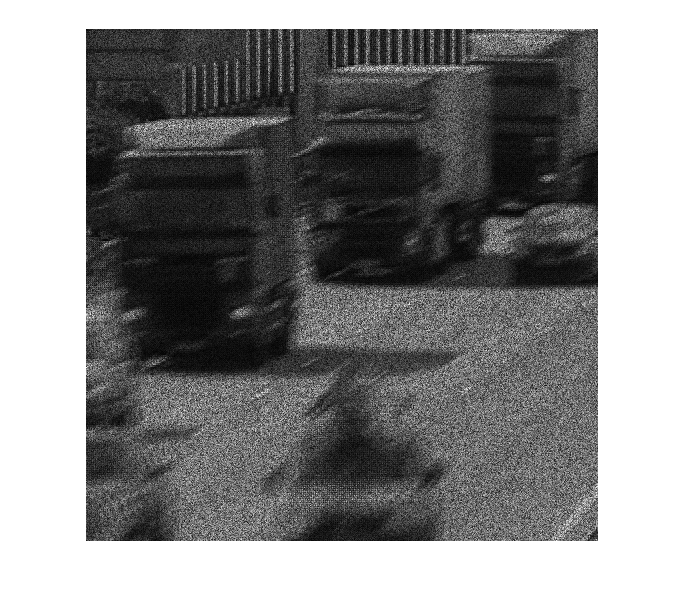

% iterative show
img = meas_bayer;
iter_num = size(img,3);

for k = 1:iter_num 
    figure, imshow(img(:,:,k),[])
end

% combine mask dataset generate [independent code block]
% run dir: E:\project\CACTI\CI algorithm\dvp\dvp_inv\dataset
load('init_test.mat')
init_mask = mask_bayer;
% combine_matrix = [1 1 0 0; 0 1 1 0; 0 0 1 1; 1 1 0 1]; % combine1
combine_matrix = [1 1 0 0; 0 1 1 0; 0 0 1 1; 0 1 0 1]; % combine2
rank(combine_matrix)

ans = 4

mask_bayer = combine_mask(init_mask,combine_matrix);
mean(mask_bayer,'a')

ans = single
0.9999


coded_frame = single(mask_bayer).*single(orig_bayer);
meas_bayer = sum(coded_frame, 3);
mean(orig_bayer,'a')

ans = 115.9300

mean(meas_bayer,'a')

ans = single
463.4922


% normalize
mask_max = max(mask_bayer,[],'a')

mask_max = single
1.9979

mask_bayer = mask_bayer./ mask_max;
meas_bayer = meas_bayer./ mask_max;
mean(mask_bayer,'a')

ans = single
0.5005

mean(meas_bayer,'a')

ans = single
231.9840

save('test.mat','combine_matrix','init_mask','orig_bayer','mask_bayer','meas_bayer', '-v7.3')
% save('test.mat','combine_matrix','init_mask','orig_bayer','mask_bayer','meas_bayer', '-append')
% save('gapfastdvdnet_test4_sigma12_combine1.mat','combine_matrix','init_mask','orig_bayer','mask_bayer','meas_bayer', '-append')
